# **Matriz de co-ocurrencia de Haralick**

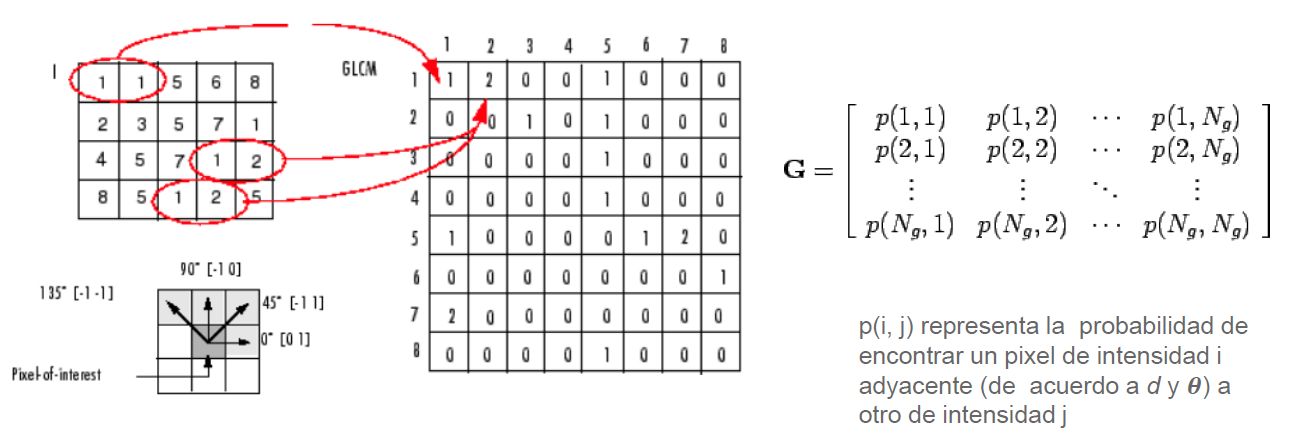

La **matriz ****de ****co-ocurrencia **refleja las relaciones espaciales entre  píxeles (distancia “d” y dirección “𝜽”)

- Se cuantifican los valores de intensidad en $N_g$** niveles** de gris.

- La matriz se obtiene para una dirección determinada entre  píxeles vecinos:** 0°, 45°, 90° y 135°**

- La comparación se realiza entre píxeles que distan una **distancia  “d”**  entre sí

En **Matlab**, podemos calcular la matriz de **co-ocurrencia usando la función **`"graycomatrix".`

`Dada una imagen de gris I:`

- `"glcm = graycomatrix(`[`I`](https://www.mathworks.com/help/releases/R2022b/images/ref/graycomatrix.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20BL%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20HS%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20OT%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20DX%20AM%20MP%20MB%20MT%20NV%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RQ%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20BT%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WB%20WL&docviewer=helpbrowser&docrelease=R2022b&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31516%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3D696GSO%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=BAFTO6&container=jshelpbrowser#bu3j4f2-1-I)`,'GrayLimits',[])"` devuelve **una matriz de co-ocurrencia** **de nivel de gris **(gray-level co-occurrence matrix is a *gray-level spatial dependence matrix)*. Por defecto, la función "graycomatrix" calcula la matriz glcm basándose en una proximidad horizontal con d=1, es decir, el `"offset=[0,1]"`.

- `"glcm = graycomatrix(I,``'Offset'``,offsets)"  `permite especificar la distancia "$d$" y la dirección "$\theta \;$". Véase la figura de abajo.

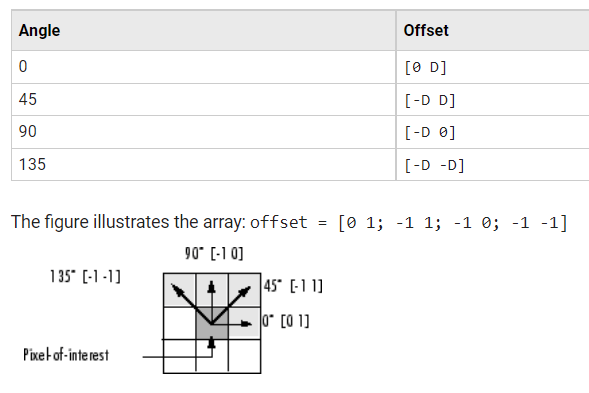

# Ejemplo 1

% Dada la siguiente imagen:
I = [ 1 1 5 6 8 8; 2 3 5 7 1 2; 1 2 3 5 6 7]

I =      1     1     5     6     8     8
     2     3     5     7     1     2
     1     2     3     5     6     7


% Calculamos la matriz glcm
% d=1, theta=0
glcm = graycomatrix(I,'GrayLimits',[])

glcm =      1     2     0     0     1     0     0     0
     0     0     2     0     0     0     0     0
     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     2     1     0
     0     0     0     0     0     0     1     1
     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1


% Calculamos la matriz glcm
% d=1, theta=0, 45, 90, 135
offset = [0 1; -1 1; -1 0; -1 -1];
glcm = graycomatrix(I,'Offset',offset,'GrayLimits',[]) % esta operación devuelve 4 matrices glcm cada una para un valor de theta diferente.

glcm = glcm(:,:,1) =

     1     2     0     0     1     0     0     0
     0     0     2     0     0     0     0     0
     0     0     0     0     2     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     2     1     0
     0     0     0     0     0     0     1     1
     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1


glcm(:,:,2) =

     0     0     1     0     0     0     0     1
     1     0     0     0     1     0     0     0
     0     0     0     0     1     0     1     0
     0     0     0     0     0     0     0     0
     1     0     0     0     0     1     0     0
     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     0


glcm(:,:,3) =

     0     1     0     0     0     0     0     1
     1     0     1     0     0     0     0     1
     1     0     0     0     1     0     0     0
     0     0 

# Calcular estadísticos a partir de la matriz GLCM

La función de Matlab `"stats = graycoprops(glcm,properties)"` calcula los estadísticos especificados en el argumento `"properties"` a partir de la matriz `glcm`.

`"graycoprops"` normaliza la matriz glcm de modo que la suma de todos sus elementos es igual a 1.

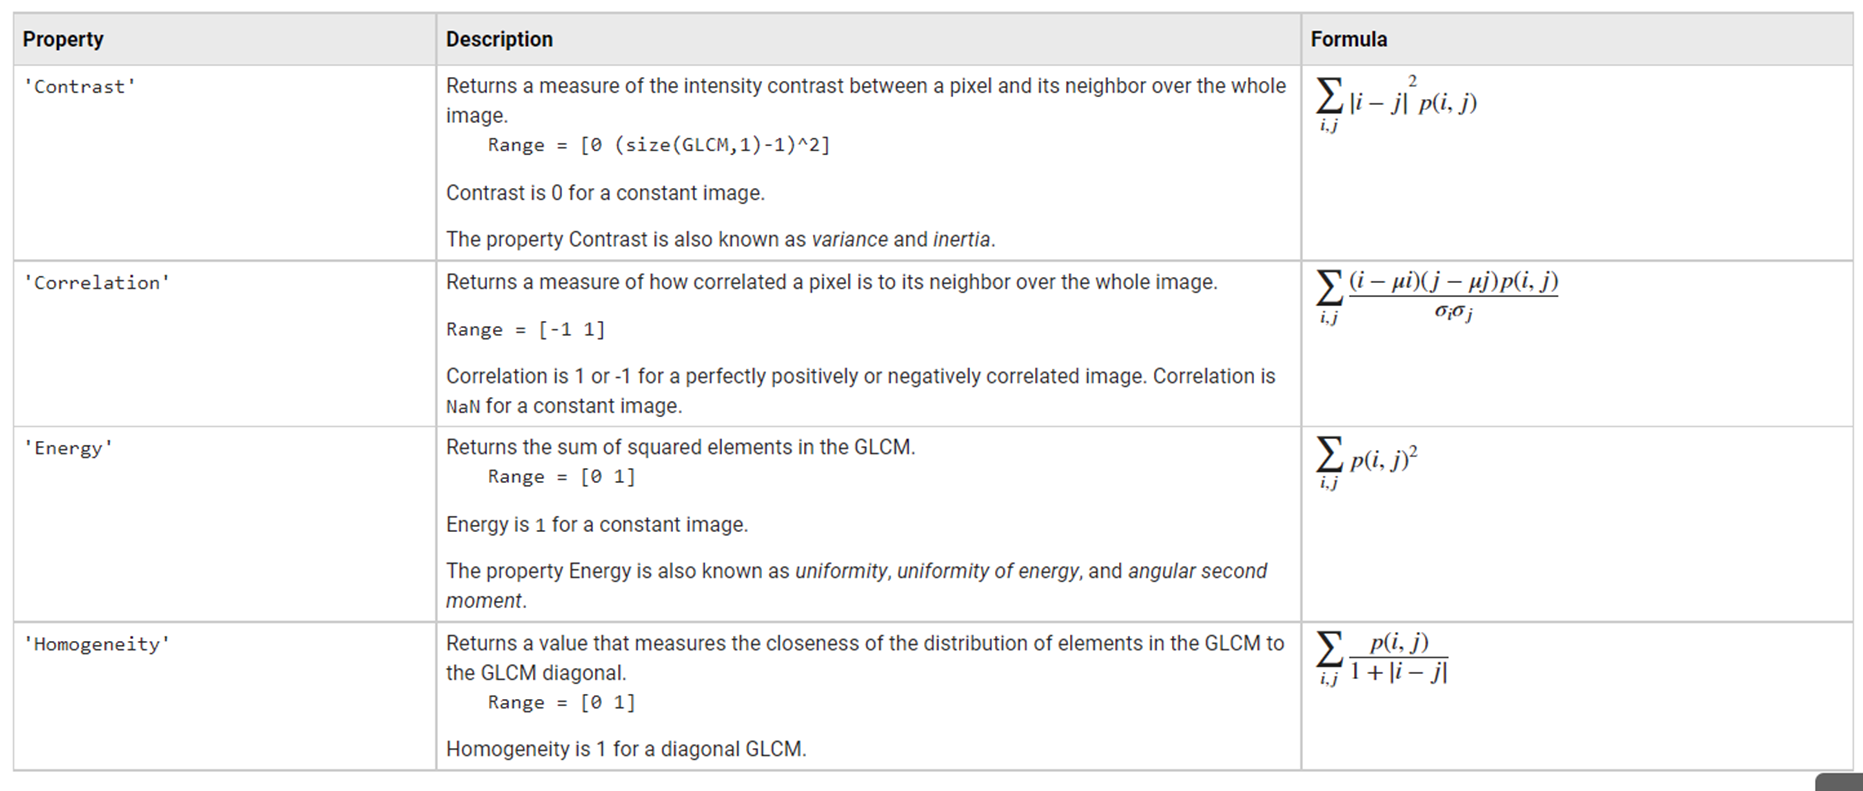

% usando las matrices glcm obtenidas en el apartado anterior, obtenemos para
% cada matriz un conjunto de estadísticos (contraste, correlación, energía
% y homogeneidad.

% Fijáros que devuelve 4 valores para cada estadístico ya que tenemos 4
% matrices.

stats = graycoprops(glcm)

stats = struct with fields:
       Contrast: [5 11.699999999999999 12.583333333333334 12.199999999999999]
    Correlation: [0.612722295960609 0.019283614847240 -0.084167698645509 -0.152080356697178]
         Energy: [0.102222222222222 0.100000000000000 0.083333333333333 0.100000000000000]
    Homogeneity: [0.478412698412698 0.314166666666667 0.383432539682540 0.481904761904762]


% sea p la primera matriz correspondiente a theta=0;
p=glcm(:,:,1);
% normalizamos la matriz de modo que la suma de sus elementos sea igual a 1
p=p./sum(p(:));

% calculamos el contraste y energia usando las formulas que aparacen en la tabla de
% arriba.
contraste = 0;
energia = 0;
for i=1:8
    for j=1:8
        contraste = contraste+abs(i-j)^2*p(i,j);
        energia = energia+ p(i,j)^2;
    end
end
contraste

contraste =      5


energia

energia =    0.102222222222222


**Cómo pueden ver no es complicado calcular los estadísticos a partir de una función de densidad.**